# Sustitución 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Una comprensión profunda de la integral como antiderivada sólo puede llevarte hasta cierto punto. Al igual que con las derivadas, existen reglas de integración que también se pueden construir mediante la combinación de funciones. El método de sustitución que se analizará en este guión en vivo se aplica a casi todas las integrales que jamás calcules. De hecho, es probable que incluso olvides que lo estás aplicando en algunos casos porque su uso resultará muy natural. 

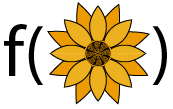

El método de sustitución te permite reemplazar una integral complicada por una más simple. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB.

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

clear g fa fb fc fu f dxGrp dgGrp ax ax1 ax2 ax3 AreaGrpdx
 

##  Visualizando variables cambiantes 

clear x
syms x %#ok<NASGU>

Puede ser contradictorio visualizar cómo un cambio de variables afecta su función o la integral resultante. Utilice esto para investigar diferentes combinaciones de funciones. 

###  Configura las funciones a usar 

f = @(x)sin(x);
g = @(x)log(x+5.001);

Elige un punto final izquierdo $a$ y un punto final derecho $b$ tal que $a \leq x \leq b$ : 

a =-3.4; b = 2.1;
if a > b
    warning("Este código asume que a<b. Por favor, ajusta tus valores en consecuencia.")
end
tVals = linspace(min(a,b),max(a,b),10000);
gVals = double(g(tVals));
fVals = double(f(gVals));

Visualiza el gráfico como $f(g(x))$ vs $x$ o $f(g(x))$ vs $g(x)$ : 

displayXvsF = 1;
clear p2
figure

[ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF);
  

Elija un tamaño de paso y un punto inicial: 

Step = 0.75; x0 = 1.1;
 
Flag = "xdx";

if ~exist("p1","var")
    if ~exist("displayXvsF","var")
        disp("Assuming default values:")
        f = @(x)sin(x);
        g = @(x)log(x+5.001);
        tVals = linspace(-3.4,2.1,10000);
        gVals = double(g(tVals));
        fVals = double(f(gVals));
        [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,1);
    else
        [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF);
    end
end

y0 = double(f(g(x0)));
y1 = double(f(g(x0+Step)));
g0 = double(g(x0));
g1 = g0+Step;
g2 = double(g(x0+Step));

switch Flag
    case "gdx"
        disp("El tamaño del paso mostrado es dg = "+Step+" y el punto inicial es g_0="+g0+".")
        if (g0+Step > max(gVals)) || (g0+Step < min(gVals))
            warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
        end
        title(ax,"Mostrando el efecto del tama\~no de paso elegido $dg =$"+Step,"Interpreter","latex")
        p1.XData = gVals;
        ax.XLim = [min(gVals) max(gVals)];
        xlabel(ax,"$g(x)$","Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [g0 g0];
            p2(2).XData = [g1 g1];
            ax.Legend.String = ["$g(x_0)$" "$g(x_0)+dg$"];
        else
            hold on
            yM = max(fVals);
            ym = min(fVals);
            p2 = plot(ax,[g0 g0],[ym yM],[g1 g1],[ym yM]);
            hold off
            legend(["" "$g(x_0)$" "$g(x_0)+dg$"],Interpreter="latex",Location="northwest")
        end
    case "xdx"
        disp("El tamaño del paso mostrado es dx = "+Step+" y el punto inicial es x_0="+x0+".") %#ok<*UNRCH>
        if (x0+Step > max(tVals)) || (x0+Step < min(tVals))
            warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
        end
        p1.XData = tVals;
        ax.XLim = [tVals(1) tVals(end)];
        t0 = x0;
        t1 = x0+Step;
        y1 = double(f(g(x0+Step)));
        xlabel(ax,"$x$","Interpreter","latex")
        title(ax,"Mostrando el efecto de un tama\~no de paso constante $dx = $"+Step,"Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [t0 t0];
            p2(2).XData = [t1 t1];
            ax.Legend.String = ["$x_0$" "$x_0+dx$"];
        else
            hold on
            p2 = plot(ax,[t0 t0],[ym yM],[t1 t1],[ym yM]);
            hold off
            legend(["" "$x_0$" "$x_0+dx$"],Interpreter="latex",Location="northwest")
        end
    case "gdg"
        disp("El tamaño del paso es dx ="+Step+".")
        disp("Por lo tanto, el tamaño del paso mostrado es dg = "+(g2-g0)+" y el punto inicial es g_0="+g0+".")
        if ~isreal(g2)
            warning("Este valor está fuera del dominio real de g. Por favor, elige un tamaño de paso diferente.")
        else
            if (g2 > max(gVals)) || (g2 < min(gVals))
                warning("Este tamaño de paso se mueve fuera de la ventana del dominio mostrada.")
            end
            title(ax,"Mostrando el efecto de la sustituci\'on en el tamaño del paso $dg = g(x_0+dx)-g(x_0)$","Interpreter","latex")
            p1.XData = gVals;
            ax.XLim = [min(gVals) max(gVals)];
            xlabel(ax,"$g(x)$","Interpreter","latex")
            if exist("p2","var")
                p2(1).XData = [g0 g0];
                p2(2).XData = [g2 g2];
                ax.Legend.String = ["$g(x_0)$" "$g(x_0+dx)$"];
            else
                hold on
                p2 = plot(ax,[g0 g0],[ym yM],[g2 g2],[ym yM]);
                hold off
                legend(["" "$g(x_0)$" "$g(x_0+dx)$"],Interpreter="latex",Location="northwest")
            end
        end
end

###  Visualice las subdivisiones en áreas enteras 

Configure las funciones y los límites a utilizar. 

clear f g p3
syms x
f(x) = sin(x); % pecado(x)
g(x) = 1/(1+x^2); % 1/(1+x^2) funciona bien, solía usar x^4
 
a =-1.2; b = 6.9;

¿Cuántos intervalos? 

NumIntervals =73;
Step = (b-a)/NumIntervals;
if Step < 0
    tVals = linspace(max(a,b),min(a,b),ceil(1000/NumIntervals)*NumIntervals);
    StepSize = ceil(1000/NumIntervals);
else
    tVals = linspace(min(a,b),max(a,b),ceil(1000/NumIntervals)*NumIntervals);
    StepSize = ceil(1000/NumIntervals);
end
gVals = double(g(tVals));
fVals = double(f(gVals));
p3 = plot(gVals,fVals);
ax3 = p3.Parent;
title(ax3,"Mostrar el \'area con signo entre $f(g(x))$ y el eje $g(x)$","Interpreter","latex")
hold on
xlabel(ax3,"$g(x)$",Interpreter="latex")
ylabel(ax3,"$f(g(x))$",Interpreter="latex")
ShowPosNegArea(ax3,fVals,gVals);

####  Animar la visualización mediante pasos de tamaño original o de sustitución 

Primero, muestre las posiciones de los intervalos definidos por un tamaño de paso constante $dg$, luego subdivida la misma región por intervalos definidos por un tamaño de paso constante $dx$ debajo del mapa $g(x_k+dx) = g(a+kdx)$ donde $x_k$ es el punto inicial del intervalo $k^{\text{th}}$. De manera equivalente, $x = a$ es el límite inferior del intervalo correspondiente. 

idx = 1:StepSize:length(tVals);
ConstdgDomain = linspace(gVals(1),gVals(end),length(idx));
ConstfVals = double(f(ConstdgDomain));
RunAnimateStripes = true;     
MaxContrast = round(1-ax3.Parent.Color);
if RunAnimateStripes
    delete(ax3.Children(1:end-2))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("Con constante $dg$","Interpreter","latex")
    dgGrp = AnimateStripes(ax3,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,ContrastColor=MaxContrast);
    dgGrp = AddStartEnd(ax3,ConstdgDomain,dgGrp);
    dgGrp.Visible = "off";
    subtitle("Con constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax3,gVals,fVals,idx,dxGrp,ContrastColor=MaxContrast);
    dxGrp = AddStartEnd(ax3,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    dgGrp = AnimateStripes(ax3,ConstdgDomain,ConstfVals,1:length(idx),dgGrp,flag=0,ContrastColor=MaxContrast);
    dgGrp.Visible = "off";
    subtitle("Mostrando constante $dx$","Interpreter","latex")
    dxGrp = AnimateStripes(ax3,gVals,fVals,idx,dxGrp,flag=0,ContrastColor=MaxContrast);
    hold off
end
SetXTicks(ax3,[gVals(1) gVals(end)],["g(a)" "g(b)"])

####  Mostrar solo un conjunto de pasos 

Si la casilla de verificación está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dg$. Si la casilla de verificación no está seleccionada, el gráfico muestra la región subdividida en intervalos de tamaño constante $dx$. En el último caso, los extremos del intervalo trazado ocurren después de las longitudes $dg = g'(x)dx$. Debido a que esto depende del valor de $g'(x)$, puede ser una transformación lineal, pero también puede ser altamente no lineal. 

Flag = true;     
if Flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Mostrando constante $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Mostrando constante $dx$ steps","Interpreter","latex")
end

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña** View **y cambie a **Output inline**. Como alternativa, seleccione **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

function [ax,p1,yM,ym] = CreateBasePlot(tVals,gVals,fVals,displayXvsF)
p1 = plot(gVals,fVals);
ax = p1.Parent;
ylabel(ax,"$f(g(x))$","Interpreter","latex")

if displayXvsF
    p1.XData = tVals;
    ax.XLim = [tVals(1) tVals(end)];
    title(ax,"Trazado de $f(x)$ contra $x$","Interpreter","latex")
    xlabel(ax,"$x$","Interpreter","latex")
else
    p1.XData = gVals;
    ax.XLim = [min(gVals) max(gVals)];
    title(ax,"Trazado de $f(x)$ contra $g(x)$","Interpreter","latex")
    xlabel(ax,"$g(x)$","Interpreter","latex")
end

yM = ax.YLim(2);
ym = ax.YLim(1);
end

function [posRegs,negRegs,allOrderedRegs] = FindSignSwitchIndexes(fVals,dVals,f0)
% fVals es un vector de dobles que se compara con una constante
% f0 en puntos dados por dVals, un vector de dobles del mismo tamaño.
%  Cada región no negativa/no positiva es una fila en posRegs/negRegs,
%  respectivamente La primera y la última columna son indicadores
% (1/0) que indican (sí/no) la necesidad de interpolación al principio/final
% de la región La segunda columna es el índice en fVals/dVals del
% primer par en esa región La tercera columna es el índice en fVals/dVals
% del último par en esa región Si no hay pares fVals/dVals en la
% región, la segunda y tercera columnas contendrán NaN allOrderedRegs
% combina posRegs y negRegs con una quinta columna que *--- * rastrea
% el signo (1 para positivo, -1 para negativo) en el orden en que
% ocurren moviéndose a través de dVals

ddVals = dVals(2:end)-dVals(1:end-1);

posDU = ddVals > 0;
zeroDU = ddVals == 0;
negDU = ones(size(ddVals))-posDU-zeroDU;

posF = fVals>=f0;
negF = fVals<=f0;

posPosVals = (posDU + posF(1:end-1) + posF(2:end))==3;
negNegVals = (negDU + negF(1:end-1) + negF(2:end))==3;
allPosVals = posPosVals + negNegVals;
startPosRegIdx = find((allPosVals - [0 allPosVals(1:end-1)])==1);
endPosRegIdx = find(([allPosVals(2:end) 0] - allPosVals)==-1);
if size(startPosRegIdx) ~= size(endPosRegIdx)
    ME = MException("IndexFinder:PairFailure","Regiones de inicio/fin no coincidentes");
    throw(ME)
end
posRegs = zeros([length(startPosRegIdx),4]);
posRegs(:,2) = startPosRegIdx';
posRegs(:,3) = endPosRegIdx';

posNegVals = (posDU + negF(1:end-1) + negF(2:end))==3;
negPosVals = (negDU + posF(1:end-1) + posF(2:end))==3;
allNegVals = posNegVals + negPosVals;
startNegRegIdx = find((allNegVals - [0 allNegVals(1:end-1)])==1);
endNegRegIdx = find(([allNegVals(2:end) 0] - allNegVals)==-1);
if size(startNegRegIdx) ~= size(endNegRegIdx)
    ME = MException("IndexFinder:PairFailure","Regiones de inicio/fin no coincidentes");
    throw(ME)
end
negRegs = zeros([length(startNegRegIdx),4]);
negRegs(:,2) = startNegRegIdx';
negRegs(:,3) = endNegRegIdx';

allZeroVals = zeroDU;

regIdentified = allPosVals + allNegVals + allZeroVals;

interpIdx = find(regIdentified == 0);
for k = 1:length(interpIdx)
    if ismember(interpIdx(k)+1,startPosRegIdx)
        idx = startPosRegIdx==(interpIdx(k)+1);
        posRegs(idx,1) = 1;
    elseif ismember(interpIdx(k)+1,startNegRegIdx)
        idx = startNegRegIdx==(interpIdx(k)+1);
        negRegs(idx,1) = 1;
    elseif (posDU(interpIdx(k)) && posF(interpIdx(k)+1))||(negDU(interpIdx(k)) && negF(interpIdx(k)+1))
        posRegs = [posRegs;1 nan nan 1]; %#ok<AGROW>
    elseif (negDU(interpIdx(k)) && posF(interpIdx(k)+1))||(posDU(interpIdx(k)) && negF(interpIdx(k)+1))
        negRegs = [negRegs;1 nan nan 1]; %#ok<AGROW>
    else
        warning("Valor de índice no coincidente marcado para interpolación.")
    end
    if ismember((interpIdx(k)-1),endPosRegIdx)
        idx = endPosRegIdx==(interpIdx(k)-1);
        posRegs(idx,4) = 1;
    elseif ismember((interpIdx(k)-1),endNegRegIdx)
        idx = endNegRegIdx==(interpIdx(k)-1);
        negRegs(idx,4) = 1;
    end
end

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);

allRegs = [posRegs ones([numPosRegs 1]);...
    negRegs -1*ones([numNegRegs 1])];
allOrderedRegs = sortrows(allRegs,2);
end


function xz = FindInterpVal(xl,xr,fl,fr,f0)
% FindInterpVals toma las coordenadas de dos puntos (xl,fl) y (xr,fr) y un
% valor intermedio f0 entre fl y fr y devuelve la coordenada xz
% estimando dónde la línea entre ellos cruza el valor y = f0
if (fr-f0)*(fl-f0)>=0
    ME = MException("InterpVal:IntervalError","f0 ("+f0+") no está entre fl ("+fl+") y fr ("+fr+")");
    throw(ME)
end
%% Calcular la pendiente entre (xl,fl) y (xr,fr)
mf = (fr-fl)/(xr-xl);
%% Resolviendo la aproximación lineal f0 = mf*(xz-xl)+fl para xz
xz = (f0-fl)/mf+xl;

end

function varargout = ShowPosNegArea(ax,fVals,dVals,opts)
arguments
    ax
    fVals
    dVals
    opts.f0 = 0
    opts.overlapsFlag = 2
    opts.pnFlag = 0
end
%trama(ax,dVals,fVals,"k")
hold on
[posRegs,negRegs,allRegs] = FindSignSwitchIndexes(fVals,dVals,opts.f0);
cols = ["b" "r"];

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);
[numRegs,~] = size(allRegs);

if opts.overlapsFlag == 1
    alphaVal = 1/ceil(numRegs/2);
elseif opts.overlapsFlag == 2
    alphaVal = .5;
else
    alphaVal = 1;
end

if opts.pnFlag
    posGrp = DrawColoredPolys(ax,fVals,dVals,posRegs,numPosRegs,cols(1),opts.f0,alphaVal);
    negGrp = DrawColoredPolys(ax,fVals,dVals,negRegs,numNegRegs,cols(2),opts.f0,alphaVal);
    varargout{1} = posGrp;
    varargout{2} = negGrp;
else
    allGrp = DrawColoredPolys(ax,fVals,dVals,allRegs,numRegs,cols(1),opts.f0,alphaVal);
    varargout{1} = allGrp;
end

hold off
end

function polyGrp = DrawColoredPolys(ax,fVals,dVals,Regs,numRegs,col,f0,alphaVal)
polyGrp = hggroup;
for k = 1:numRegs
    xVals = dVals(Regs(k,2):Regs(k,3)+1);
    yVals = fVals(Regs(k,2):Regs(k,3)+1);
    if Regs(k,1)
        xnew = FindInterpVal(dVals(Regs(k,2)-1),xVals(1),...
            fVals(Regs(k,2)-1),yVals(1),f0);
        xVals = [xnew xVals]; %#ok<AGROW>
        yVals = [f0 yVals]; %#ok<AGROW>
    end
    if Regs(k,4)
        xnew = FindInterpVal(xVals(end),dVals(Regs(k,3)+2),...
            yVals(end),fVals(Regs(k,3)+2),f0);
        xVals = [xVals xnew]; %#ok<AGROW>
        yVals = [yVals f0]; %#ok<AGROW>
    end
    x = [xVals flip(xVals)];
    y = [f0*ones(size(yVals)) flip(yVals)];
    patch(ax,x,y,col,"FaceAlpha",alphaVal,"Parent",polyGrp);
    pause(.1)
end
end

function lineGroup = AddStartEnd(ax,x,lineGroup)
plot(ax,[x(end) x(end)],ax.YLim,"r-","LineWidth",2,"Parent",lineGroup);
plot(ax,[x(1) x(1)],ax.YLim,"c-","LineWidth",2,"Parent",lineGroup);
end

function lineGroup = AnimateStripes(ax,x,y,idx,lineGroup,opts)
arguments
    ax
    x
    y
    idx
    lineGroup
    opts.flag = true
    opts.ContrastColor = [0 0 0]
end
% x e y tienen la misma longitud, por lo que esto simplemente crea y agrega a
% la colección lineGroup relevante de líneas trazadas en los valores de índice
% dados por idx
% si la bandera está configurada , mostrar como animación
if length(idx)>1
    p = plot(ax,[x(idx(1)) x(idx(1))],[0 y(idx(1))],"Parent",lineGroup,Color=opts.ContrastColor);
    for k = 2:length(idx)
        copyobj(p,lineGroup)
        if x(idx(k))>= x(idx(k-1))
            lineGroup.Children(k).Color = opts.ContrastColor;
            lineGroup.Children(k).LineWidth = 1;
        else
            lineGroup.Children(k).Color = "y";
            lineGroup.Children(k).LineWidth = 1;
        end
        lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
        lineGroup.Children(k).YData = [0 y(idx(k))];
        if opts.flag
            drawnow
        end
    end
end
lineGroup = AddStartEnd(ax,x,lineGroup);
end

function SetXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end